clc
clear all


## 单面点云

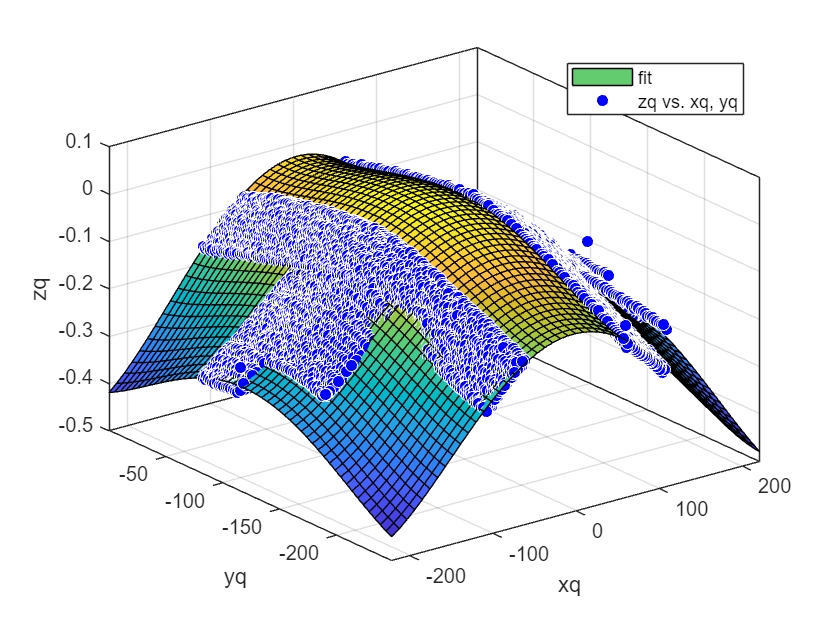

data_1=importdata("C:\Users\10571\Desktop\代办事项\四川高纳\输出点A_右平面.txt");
data_2=importdata("C:\Users\10571\Desktop\代办事项\四川高纳\输出点A_左平面.txt");
data=[data_1(:,1:3);data_2(:,1:3)];
% data = data_1;

xq=data(:,1);
yq=data(:,2);
zq=-data(:,3);
%% 拟合
n = 4;%拟合方程次数
[f  gof] = createFit(xq, yq, zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

-0.027436 + 0.00018254*Y + 1.8412e-05*Y*Y + 1.5764e-07*Y*Y*Y + 3.2258e-10*Y*Y*Y*Y + -2.9535e-07*X*Y + -5.277e-09*X*Y*Y + -4.8825e-12*X*Y*Y*Y + -3.3334e-08*X*X*Y + -1.084e-10*X*X*Y*Y + -1.8164e-11*X*X*X*Y + 7.7597e-11*X*X*X*X 


disp(gof)

           sse: 0.4709
       rsquare: 0.9901
           dfe: 10296
    adjrsquare: 0.9901
          rmse: 0.0068



## 两面点云

% data_r_1 = importdata("C:\Users\10571\Desktop\四川高纳\输出点B_右平面.txt");
% data_r_2 = importdata("C:\Users\10571\Desktop\四川高纳\输出点A_右平面.txt");
% data_l_1 = importdata("C:\Users\10571\Desktop\四川高纳\输出点B_左平面.txt");
% data_l_2 = importdata("C:\Users\10571\Desktop\四川高纳\输出点A_左平面.txt");
% 
% data_r_1  = data_r_1(2:end,1:3);
% data_r_2  = data_r_2(2:end,1:3);
% data_l_1  = data_l_1(2:end,1:3);
% data_l_2  = data_l_2(2:end,1:3);
% M = [-1,0,0;0,1,0;0,0,1];
% data_r_1 = data_r_1*M';
% data_l_2 = data_l_2*M';
% data_l = [data_l_2;data_r_1];
% data_r = [data_r_1;data_l_2];
% 
% data = [data_l;data_r];
% [X,Y,Z] = PreprocessDate(data,2); 
% n = 4;%拟合方程次数
% [f  gof] = createFit(X, Y, Z, n);
% P = coeffvalues(f);%多项式系数向量
% s = dispf(P,n,n);
% disp(s)
% disp(gof)
